# Bank Marketing: revision de datos paso a paso

Igual que con Ecoli: cada seccion deja una tabla en el workspace para abrir en Classification Learner con Response = "clase". Se usa bank.csv, que es la muestra del 10% (4521 clientes). El completo tiene 45211 y con todos los modelos de la app se demora demasiado.

clear; close all; clc

## Paso 0: cargar y mirar el dato crudo

T = readtable('../data/bank/bank.csv', 'Delimiter', ';', 'TextType', 'string');
T.Properties.VariableNames{end} = 'clase';

% las de texto se pasan a categorica para que la app las entienda
texto = {'job','marital','education','default','housing','loan','contact','month','poutcome','clase'};
for k = 1:numel(texto)
    T.(texto{k}) = categorical(T.(texto{k}));
end

T0_crudo = T;
disp(head(T0_crudo))

    age         job         marital    education    default    balance    housing    loan    contact     day    month    duration    campaign    pdays    previous    poutcome    clase
    ___    _____________    _______    _________    _______    _______    _______    ____    ________    ___    _____    ________    ________    _____    ________    ________    _____

    30     unemployed       married    primary        no        1787        no       no      cellular    19      oct        79          1          -1        0        unknown      no  
    33     services         married    secondary      no        4789        yes      yes     cellular    11      may       220          1         339        4        failure      no  
    35     management       single     tertiary       no        1350        yes      no      cellular    16      apr       185          1         330        1        failure      no  
    30     management       married    tertiary       no        1476        yes

summary(T0_crudo)


T0_crudo: 4521×17 table

Variables:

    age: double
    job: categorical (12 categories)
    marital: categorical (3 categories)
    education: categorical (4 categories)
    default: categorical (2 categories)
    balance: double
    housing: categorical (2 categories)
    loan: categorical (2 categories)
    contact: categorical (3 categories)
    day: double
    month: categorical (12 categories)
    duration: double
    campaign: double
    pdays: double
    previous: double
    poutcome: categorical (4 categories)
    clase: categorical (2 categories)

Statistics for applicable variables:

                 NumMissing       Min       Median        Max            Mean              Std      

    age              0              19         39           87           41.1701           10.5762  
    job              0                                                                              
    marital          0                                                                      

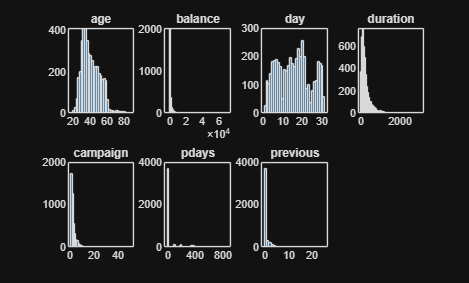


% distribucion de las numericas
numericas = {'age','balance','day','duration','campaign','pdays','previous'};
figure('Name', 'Histogramas crudo');
for k = 1:7
    subplot(2,4,k); histogram(T.(numericas{k})); title(numericas{k});
end

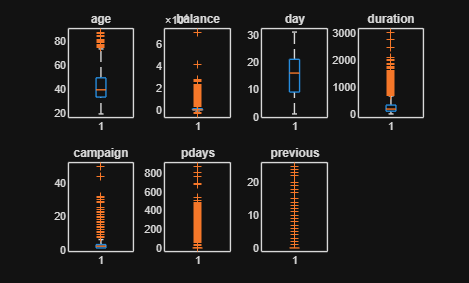


% cada una en su boxplot porque estan en escalas muy distintas
% (balance llega a 71188 y campaign a 50)
figure('Name', 'Boxplots crudo');
for k = 1:7
    subplot(2,4,k); boxplot(T.(numericas{k})); title(numericas{k});
end

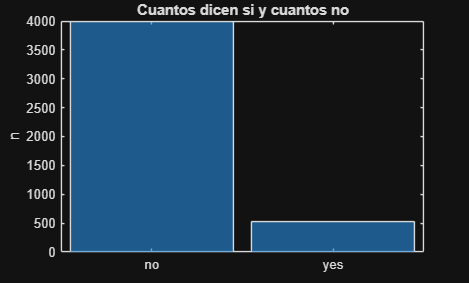


% balance de la clase
figure('Name', 'Balance de clases');
histogram(T.clase); title('Cuantos dicen si y cuantos no'); ylabel('n');

disp(countcats(T.clase)')

        4000         521



disp(categories(T.clase)')

    {'no'}    {'yes'}




% Lo que se ve: balance, duration, campaign y previous tienen colas
% larguisimas. pdays vale -1 en casi todas las filas (significa "nunca lo
% habian llamado"). La clase esta desbalanceada: 4000 no contra 521 si.

## Paso 1: corregir outliers y variables raras

T1_outliers = T0_crudo;

% duration es cuanto duro la llamada. Eso solo se sabe despues de llamar,
% asi que no sirve para predecir a quien llamar. Se quita.
T1_outliers.duration = [];

% pdays = -1 no es un numero de dias, es "nunca contactado". Se convierte
% en una variable si/no y el -1 se vuelve 0.
T1_outliers.contactado_antes = double(T1_outliers.pdays >= 0);
T1_outliers.pdays(T1_outliers.pdays < 0) = 0;

% regla del 1.5*IQR en las que tienen cola larga, recortando al borde
recortar = {'age','balance','campaign','pdays','previous'};
for k = 1:numel(recortar)
    x = T1_outliers.(recortar{k});
    q = quantile(x, [0.25 0.75]);
    li = q(1) - 1.5*(q(2)-q(1));
    ls = q(2) + 1.5*(q(2)-q(1));
    if ls == li           % pdays y previous son casi todo ceros, IQR = 0
        ls = quantile(x, 0.99);   % a esas se les recorta el 1% mas alto
    end
    fprintf('%s: %d valores fuera de [%.0f, %.0f]\n', recortar{k}, sum(x<li | x>ls), li, ls);
    x(x < li) = li;  x(x > ls) = ls;
    T1_outliers.(recortar{k}) = x;
end

age: 38 valores fuera de [9, 73]
balance: 506 valores fuera de [-2048, 3596]
campaign: 318 valores fuera de [-2, 6]
pdays: 41 valores fuera de [0, 370]
previous: 34 valores fuera de [0, 8]


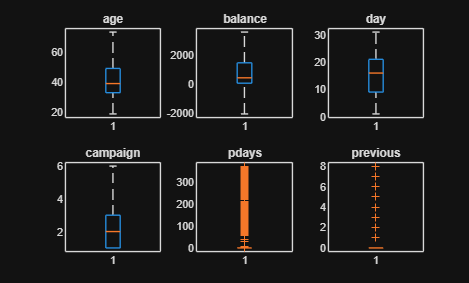


numericas = {'age','balance','day','campaign','pdays','previous'};
figure('Name', 'Boxplots sin outliers');
for k = 1:6
    subplot(2,3,k); boxplot(T1_outliers.(numericas{k})); title(numericas{k});
end

## Paso 2: balancear las clases

Hay 4000 "no" y 521 "si". Se toman al azar 521 "no" para que queden iguales (submuestreo). Se pierden datos pero el modelo deja de aprender a decir siempre "no".

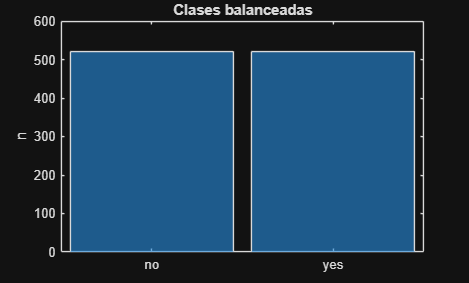

rng(1)
si = T1_outliers(T1_outliers.clase == "yes", :);
no = T1_outliers(T1_outliers.clase == "no", :);
no = no(randperm(height(no), height(si)), :);
T2_balanceado = [si; no];

figure('Name', 'Balance despues');
histogram(T2_balanceado.clase); title('Clases balanceadas'); ylabel('n');

fprintf('Antes: %d filas. Despues: %d filas (%d de cada clase).\n', ...
    height(T1_outliers), height(T2_balanceado), height(si));

Antes: 4521 filas. Despues: 1042 filas (521 de cada clase).


## Paso 3: estandarizar (media 0, desviacion 1)

Solo las numericas. Las categoricas se dejan como estan.

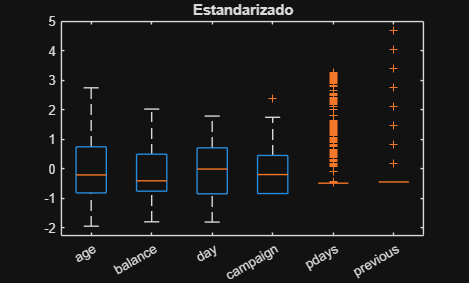

T3_estandarizado = T2_balanceado;
for k = 1:numel(numericas)
    T3_estandarizado.(numericas{k}) = zscore(T2_balanceado.(numericas{k}));
end
figure('Name', 'Boxplot estandarizado');
boxplot(T3_estandarizado{:, numericas}, 'Labels', numericas); title('Estandarizado');

## Paso 4: normalizar (entre 0 y 1)

Parte del balanceado, no del estandarizado. Son dos alternativas.

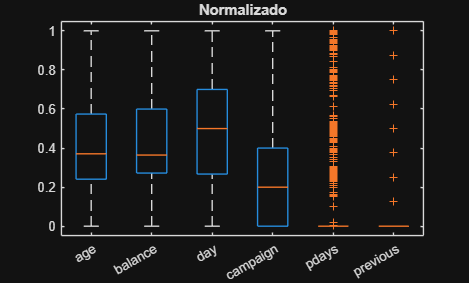

T4_normalizado = T2_balanceado;
for k = 1:numel(numericas)
    x = T2_balanceado.(numericas{k});
    T4_normalizado.(numericas{k}) = (x - min(x)) / (max(x) - min(x));
end
figure('Name', 'Boxplot normalizado');
boxplot(T4_normalizado{:, numericas}, 'Labels', numericas); title('Normalizado');

## Resumen de lo que hay en el workspace

disp('Tablas listas para Classification Learner (Response = clase):')

Tablas listas para Classification Learner (Response = clase):


disp({'T0_crudo'; 'T1_outliers'; 'T2_balanceado'; 'T3_estandarizado'; 'T4_normalizado'})

    {'T0_crudo'        }
    {'T1_outliers'     }
    {'T2_balanceado'   }
    {'T3_estandarizado'}
    {'T4_normalizado'  }

